# 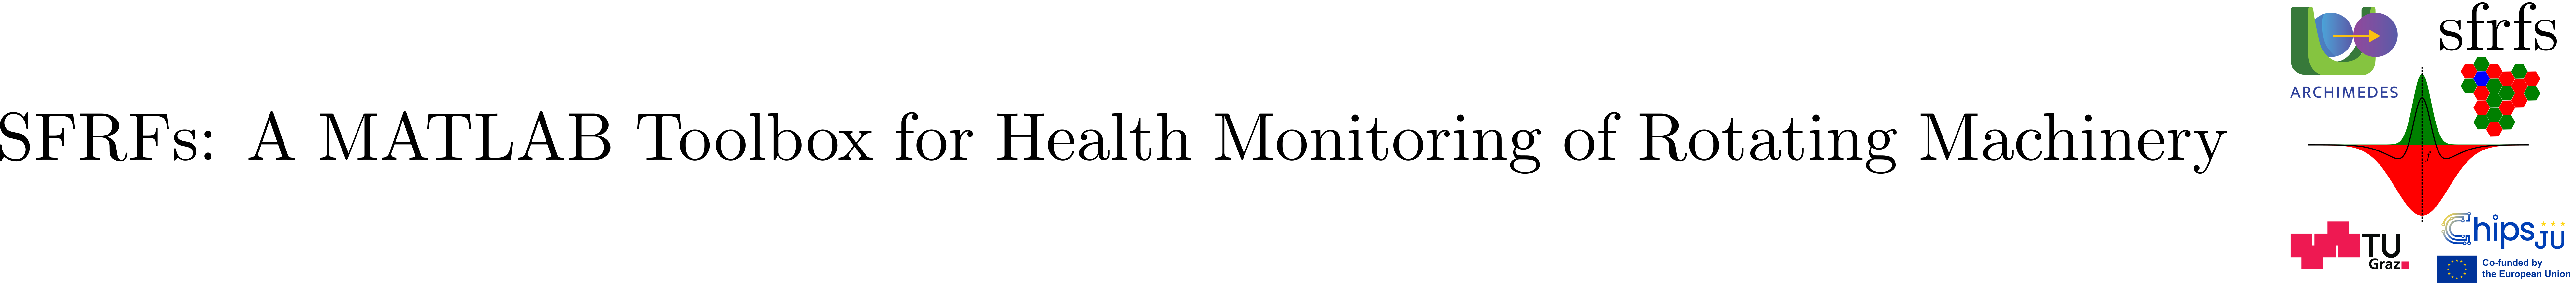

# createXJTUSYEnsemble

## Summary

Loads the the XJTU-SY rolling bearing run-to-failure dataset, processes vibration snapshots from each bearing, and generates a `fileEnsembleDatastore` compatible with MATLAB’s Predictive Maintenance Toolbox.

**Key Features:**

- Handles all three operating conditions (35Hz12kN, 37.5Hz11kN, 40Hz10kN) and all bearings under each condition.

- Reads horizontal and vertical vibration signals from `.csv` snapshot files.

- Tracks metadata for each snapshot (Bearing label, Snapshot index).

- Saves each bearing’s processed data as a `.mat` file in a user-specified output folder.

- Supports progress reporting.

**Inputs (Name-Value Pairs):**

- `datasetFolder` – Path to the unzipped XJTU-SY dataset; if unspecified, a folder selection dialog appears.

- `outputFolder` – Path where processed `.mat` files will be saved; if unspecified, a folder selection dialog appears.

- `progressMode` – `"text"` (default), `"gui"`, or `"none"`.

**Output:**

- `ensemble` – A `fileEnsembleDatastore` object referencing the processed data.

## Description

Wang et al's [**XJTU-SY**](https://github.com/WangBiaoXJTU/xjtu-sy-bearing-datasets) dataset consists of 15 run-to-failure tests conducted on a testbed that included an AC induction motor, closed-loop speed controller, a hydraulic loading system, a support shaft, and two accelerometers.

### Vibration signals

Two accelerometers model PCB 352C33 with a frequency range of 0.5 to 10 kHz (±5%), 0.3 to 15 kHz (±10%) and a resonant frequency greater or equal to 50 kHz oriented horizontally and vertically (both perpendicular to the shaft) were used in the testbed. A frequency of 25.6 kHz was used to sample the vibration data. Signal snapshots (see [ParameterSnapshot](matlab:open('./ParametersSnapshot.mlx'))) were recorded at regular intervals, each with a duration of 1.28 seconds (a window of 32768 samples). The interval between the first samples of consecutive snapshots is 1 minute.

### Signal snapshots

Each bearing is uniquely identified by a label (e.g., *Bearing1_1*, *Bearing2_3*), and the dataset is organized into snapshots. For each snapshot, both horizontal and vertical acceleration signals are available, along with associated metadata such as rotor speed, load (see [OperatingConditions](matlab:open('./OperatingConditions.mlx'))), and a unique snapshot index.

### Operating conditions 

The mapping between bearing labels and operating conditions is shown in Table 1.

**Table 1**. Mapping of bearing labels to operating conditions in the  [**XJTU-SY**](https://github.com/WangBiaoXJTU/xjtu-sy-bearing-datasets) dataset.

### Failure Criterion

A bearing failed when its maximum vibration amplitude surpassed ten times its initial normal operating level. This relative threshold ensured consistent and reproducible failure detection.

### Diagnosis after failure

Table 2 summarizes the different fault modes identified after failure.

Table 2. Diagnosis after failure for the different bearings.

### Data ensembles

This class converts the [**XJTU-SY**](https://github.com/WangBiaoXJTU/xjtu-sy-bearing-datasets) run-to-failure bearing dataset into a MATLAB [fileEnsembleDatastore](https://www.mathworks.com/help/predmaint/ref/fileensembledatastore.html) compatible with the [Predictive Maintenance Toolbox](https://www.mathworks.com/products/predictive-maintenance.html). Each ensemble member corresponds to a bearing and contains all snapshots recorded during its operational life.

The ensemble includes all relevant variables: horizontal and vertical acceleration signals, operational conditions (speed and load), and lifetime annotations.

## Example

### Ensemble creation

As the transformation may take some time to complete, the function provides two feedback mechanisms that can be selected via the named parameter **progressMode**. The function requires two folders, **datasetFolder** and **outputFolder**, for its operation. If these folders are not specified, the function will prompt the user to select them interactively.

#### Graphical progress bar

Creating an ensemble with a graphical progress bar can be initiated either from a live script, such as this one, or from the MATLAB command line. To enable the graphical mode, the parameter **progressMode** must be set to **gui**.

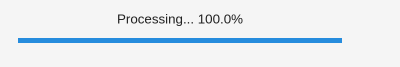

% Create an ensemble with folder selection dialogs and a GUI progress bar
ensemble = data.createXJTUSYEnsemble("progressMode","gui");


% Alternatively, specify the dataset and output folders programmatically
% ensemble = data.createXJTUSYEnsemble( ...
%       "datasetFolder","XJTU-SY_Bearing_Datasets", ...
%       "outputFolder","ensemble_datastore");

The function will open a file selector:

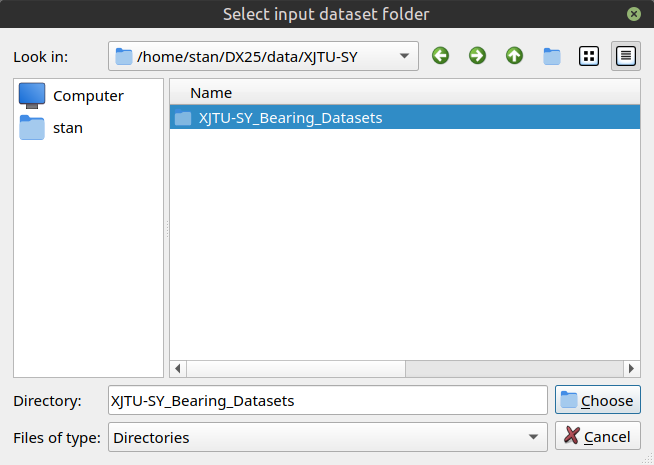

Figure 1. Selection of  [**XJTU-SY**](https://github.com/WangBiaoXJTU/xjtu-sy-bearing-datasets) dataset root folder.

Here you need to select the root folder of the  [**XJTU-SY**](https://github.com/WangBiaoXJTU/xjtu-sy-bearing-datasets) dataset. The structure of the dataset starting in the root folder is shown in Table 3.

**Table 3**. File organization of  [**XJTU-SY**](https://github.com/WangBiaoXJTU/xjtu-sy-bearing-datasets) dataset.

After selecting the root folder the function will ask you to specify the output folder where the ensemble will be written.

## 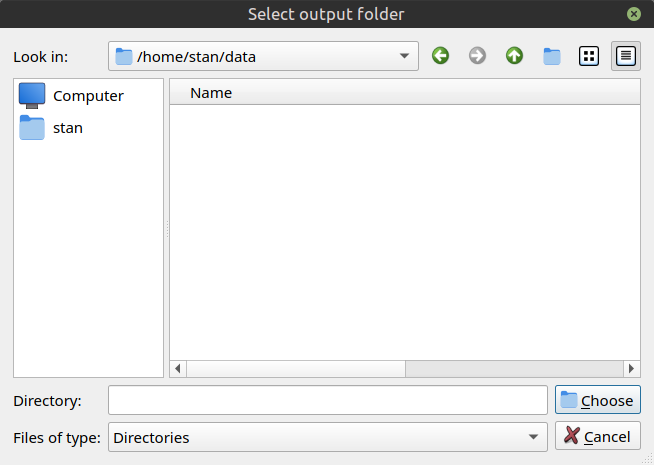

**Figure 2**. Selection of location for the output ensemble.

A progress bar will appear reporting the progress in the processing of the files.

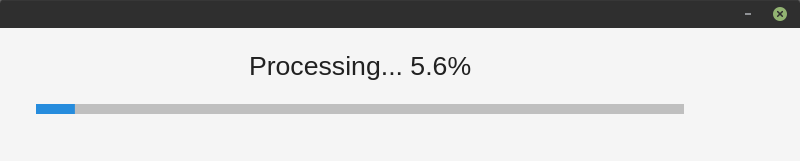

**Figure 3**. Progress in generation of ensemble.

After the transformation is complete there will be 15 MATLAB files with the ensemble members (one per test bearing).

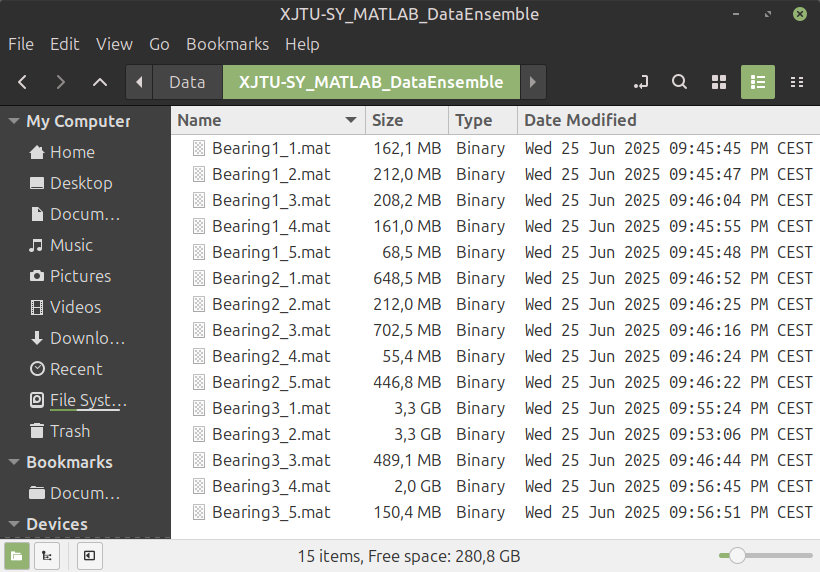

**Figure 4**. Data ensemble generated in the selected output folder.

We can get a glance of the ensemble by displaying a few rows:

% Show the first few rows of the ensemble
preview(ensemble)

ans = 8×7 table
       Label        SnapshotIndex    HorizontalAcceleration    VerticalAcceleration    Speed    Load    Lifetime
    ____________    _____________    ______________________    ____________________    _____    ____    ________

    "Bearing1_1"           1            {32768×1 double}         {32768×1 double}       35       12       123   
    "Bearing1_1"          10            {32768×1 double}         {32768×1 double}       35       12       123   
    "Bearing1_1"         100            {32768×1 double}         {32768×1 double}       35       12       123   
    "Bearing1_1"         101            {32768×1 double}         {32768×1 double}       35       12       123   
    "Bearing1_1"         102            {32768×1 double}         {3

#### Text based progress bar

In addition, there is an option for text based progress feedback, this is the default mode.

% Create ensemble with text progress feedback
%ensemble = data.createXJTUSYEnsemble("progressMode","text");
% Or simply
ensemble = data.createXJTUSYEnsemble();

[████████████████████████████████████████████████████████████] 9216/9216 (100.0%)


% Show the first few rows of the ensemble
preview(ensemble)

ans = 8×7 table
       Label        SnapshotIndex    HorizontalAcceleration    VerticalAcceleration    Speed    Load    Lifetime
    ____________    _____________    ______________________    ____________________    _____    ____    ________

    "Bearing1_1"           1            {32768×1 double}         {32768×1 double}       35       12       123   
    "Bearing1_1"          10            {32768×1 double}         {32768×1 double}       35       12       123   
    "Bearing1_1"         100            {32768×1 double}         {32768×1 double}       35       12       123   
    "Bearing1_1"         101            {32768×1 double}         {32768×1 double}       35       12       123   
    "Bearing1_1"         102            {32768×1 double}         {32768×1 double}       35       12       123   
    "Bearing1_1"         103            {32768×1 double}         {32768×1 double}       35       12       123   
    "Bearing1_1"         104            {32768×1 double}         {32768×1 doubl

### Ensemble fields

The resulting ensemble contains the following fields:

- `Label`: identifier of the bearing

- `SnapshotIndex`: index of the snapshot (see [ParametersSnapshot](matlab:open('./ParametersSnapshot.mlx'))). This integer sorts the snapshots chronologically.

- `HorizontalAcceleration` and `VerticalAcceleration `(see [ParametersSnapshot](matlab:open('./ParametersSnapshot.mlx'))): raw vibration signals, each as a 32768×1 double array

- `Speed` and `Load`: operating conditions (see [OperatingConditions](matlab:open('./OperatingConditions.mlx')))

- `Lifetime`: total number of snapshots until failure (in this case minutes)

## API documentation

### MATLAB help

help data.createXJTUSYEnsemble

 CREATEXJTUSYENSEMBLE Create a fileEnsembleDatastore for the XJTU-SY 
  dataset.
 
    ensemble = data.createXJTUSYEnsemble(Name,Value)
 
    Loads the XJTU-SY run-to-failure bearing dataset, processes each 
    bearing's vibration snapshots, and creates a fileEnsembleDatastore 
    compatible with MATLAB's Predictive Maintenance Toolbox.
 
    Name-Value Pair Arguments:
      "datasetFolder" - Path to the root of the unzipped XJTU-SY dataset. 
                        If not specified, a dialog will prompt the user.
      "outputFolder"  - Path where .mat files for each ensemble member will 
                        be saved. If not specified, a dialog will prompt.
      "progressMode"  - Progress indicator mode. Options:
                          "text" (default) - Text progress bar in 
                                             MATLAB interpreter.
                          "gui"            - Graphical waitbar 
                                             (for GUIs/Live Scripts).
   

### MATLAB documentation

doc data.createXJTUSYEnsemble

Opens the full class documentation in the MATLAB Help Browser, including formatted examples, links to related functions, and extended descriptions.

## Source code

Unlike the class-based entities, this helper is a standalone function, designed for the single task of creating or referencing a [`fileEnsembleDatastore`](https://www.mathworks.com/help/predmaint/ref/fileensembledatastore.html)`.`  The implementation can be found in [data.createXJTUSYEnsemble](matlab:open('../../+data/createXJTUSYEnsemble.m')).

## Test

Unit testing for the class is implemented in [testCreateXJTUSYEnsemble](matlab:open('../../../tests/testCreateXJTUSYEnsemble.m')).

% execute tests
res = runtests('Spectral Fault Receptive Fields/tests/testCreateXJTUSYEnsemble');

Running testCreateXJTUSYEnsemble
.....
Done testCreateXJTUSYEnsemble
__________



% display summary of tests
SFRFsTestUtil.printTestSummary(res,80);

Test Name                                                                        | Result
-----------------------------------------------------------------------------------------
testCreateXJTUSYEnsemble/testCreatesEnsembleDatastore                            | Passed
testCreateXJTUSYEnsemble/testMissingInputFolderThrowsError                       | Passed
testCreateXJTUSYEnsemble/testOutputFolderCreated                                 | Passed
testCreateXJTUSYEnsemble/testMatFileCountEqualsBearings                          | Passed
testCreateXJTUSYEnsemble/testEnsembleRowCount                                    | Passed



## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784)

## References

- Biao Wang, Yaguo Lei, Naipeng Li, Ningbo Li, “A Hybrid Prognostics Approach for Estimating Remaining Useful Life of Rolling Element Bearings”, IEEE Transactions on Reliability, pp. 1-12, 2018. [DOI: 10.1109/TR.2018.2882682](https://doi.org/10.1109/TR.2018.2882682).